% AE414_Group10_Project_SP23

clear

g_mars_surf = 3.721

g_mars_surf = 3.7210

g_e = 9.81

g_e = 9.8100

R_mars = 3389.5

R_mars = 3.3895e+03


tau = 170000

tau = 170000

I_sp = 350

I_sp = 350


M_0 = 30000

M_0 = 30000

M_b = 50

M_b = 50

k = 12

k = 12


m_dot = tau/(g_e*I_sp)

m_dot = 49.5122

u_eq = I_sp*g_e

u_eq = 3.4335e+03


A_f = pi*2.5^2/sin(pi/6)

A_f = 39.2699

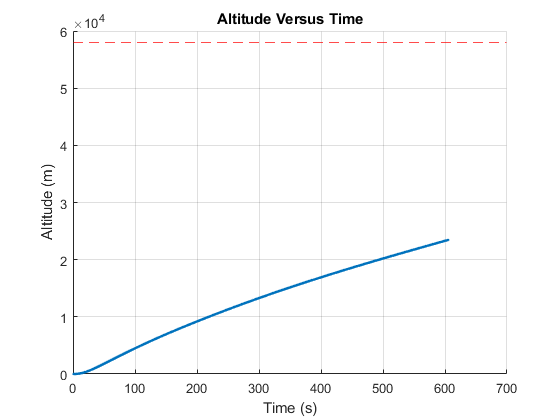


u(1) = 0;
h(1) = 0;
x(1) = 0;

% Iterations

for t = 1:(M_0 - M_b)/m_dot
    
    M(t) = M_0 - m_dot*t;
    
    g(t) = g_mars_surf*(R_mars/(R_mars + h(t)))^2;
    
    if t < 10
        theta(t) = 0;
    else
        theta(10) = k*pi/180;
        delta_theta(t) = g(t)*sin(theta(t))/u(t);
        theta(t+1) = theta(t) + delta_theta(t);
    end
         
    P(t) = 0.699*exp(-9*10^(-5)*h(t));

    if h(t)<7000
        T(t) = -31 - 9.98*10^(-4)*h(t);
    else
        T(t) = -23.4 - 2.22*10^(-3)*h(t);
    end

    rho(t) = P(t)/(0.1921*(T(t) + 273.15));
    
    Mach(t) = u(t)/sqrt(1.32*188.92*(T(t) + 273.15));
    
    if Mach(t) < 2
        C_d(t) = 0.4 + 0.3*Mach(t);
    elseif (Mach(t) < 4) && (Mach(t) > 2)
        C_d(t) = 1.2 - 0.15*Mach(t);
    else
        C_d(t) = 0.6;
    end

    D(t) = (1/2)*C_d(t)*rho(t)*u(t)^2*A_f;

    a(t) = m_dot*u_eq/M(t) - g(t)*cos(theta(t)) - D(t)/M(t);
                
    u(t+1) = u(t) + a(t);
           
    h(t+1) = h(t) + u(t)*cos(theta(t));
    
    x(t+1) = x(t) + u(t)*sin(theta(t));
    
end

t = linspace(1,length(h),length(h));

figure(1)
scatter(t,h,'.')
title('Altitude Versus Time')
xlabel('Time (s)')
ylabel('Altitude (m)')
yline(58000,'r--')
grid on

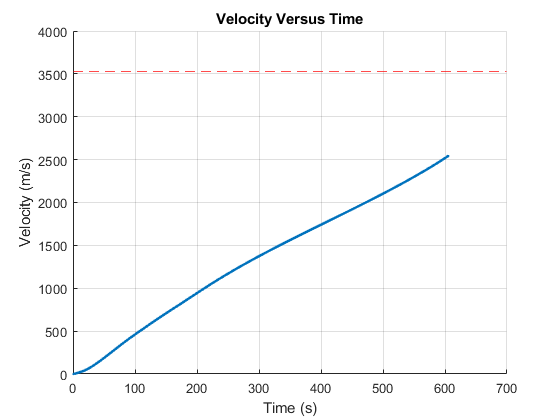


figure(2)
scatter(t,u,'.')
title('Velocity Versus Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
yline(3524.636832,'r--')
grid on

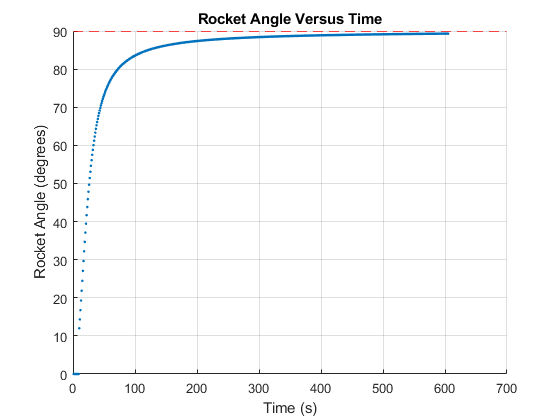


figure(3)
scatter(t,theta*180/pi,'.')
title('Rocket Angle Versus Time')
xlabel('Time (s)')
ylabel('Rocket Angle (degrees)')
yline(90,'r--')
grid on